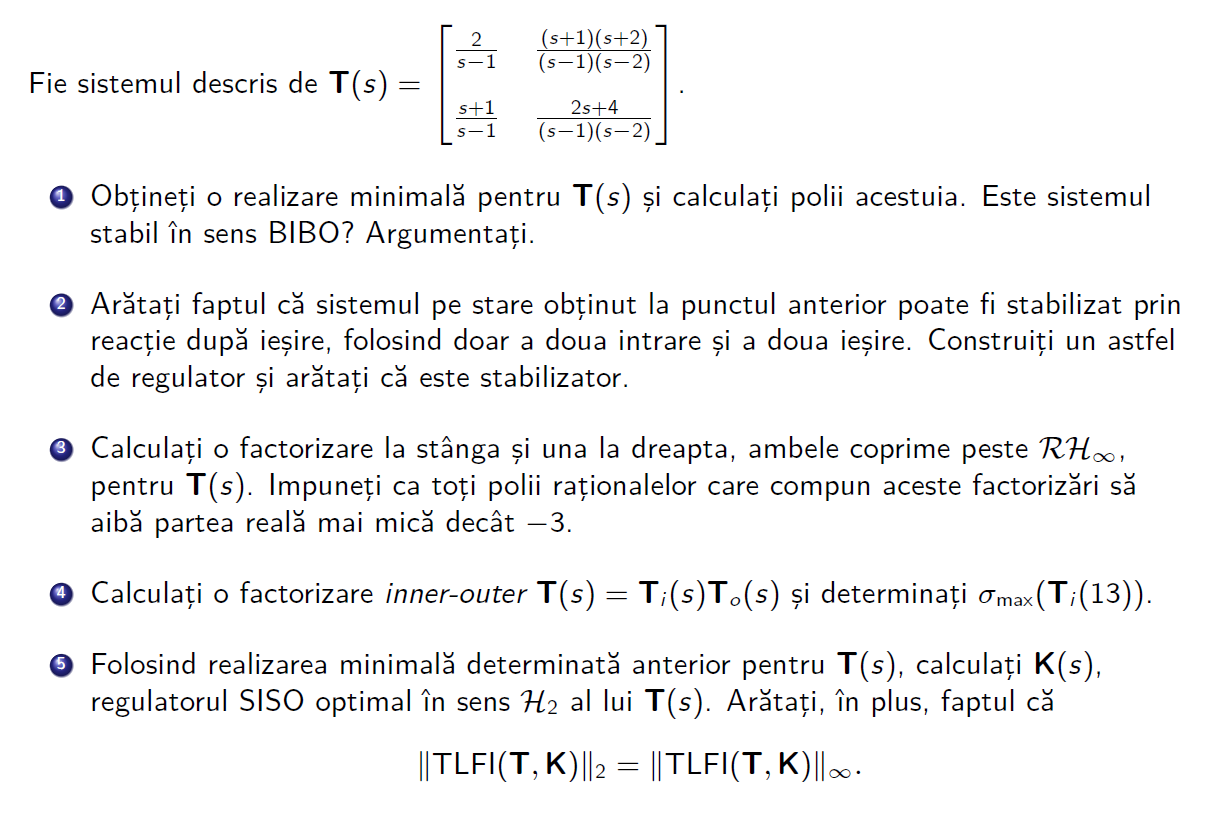

## Problema 1

clear
close all
clc

s = tf('s');
T = [2 / (s - 1), ((s + 1) * (s + 2) / ((s - 1) * (s - 2)));
     (s + 1) / (s - 1), (2*s + 4) / ((s - 1) * (s - 2))]


T =
 
  From input 1 to output...
         2
   1:  -----
       s - 1
 
       s + 1
   2:  -----
       s - 1
 
  From input 2 to output...
       s^2 + 3 s + 2
   1:  -------------
       s^2 - 3 s + 2
 
          2 s + 4
   2:  -------------
       s^2 - 3 s + 2
 
Continuous-time transfer function.



T_ss = ss(T,'min')


T_ss =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.



disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_ss.A))

    2.0000
    1.0000



disp(isstable(T_ss))

   0



Valorile proprii ale lui T_ss.A sunt din ${\mathbb{C}}^+$, deci instabile

Noi avem realizare minimala, deci inseamna ca sistemul este si controlabil si observabil

## Problema 2

Scriu $T_{\textrm{ss}} \;\textrm{in}\;\textrm{forma}\;\textrm{de}\;\textrm{matrice}\;\textrm{sa}\;\textrm{imi}\;\textrm{fie}\;\textrm{mai}\;\textrm{simplu}$

T_ss


T_ss =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


T_mat_ss = [T_ss.A, T_ss.B;
            T_ss.C, T_ss.D]

T_mat_ss =     2.5914   -1.5914    0.9701    3.4552
    0.5914    0.4086    0.9701   -0.5448
    1.7808    0.2808         0    1.0000
    0.7808    1.2808    1.0000         0


Scriem $\left(A,B_2 ,C_2 ,D_2 \right)$

A2 = T_ss.A

A2 =     2.5914   -1.5914
    0.5914    0.4086



B2 = T_ss.B(:,2)

B2 =     3.4552
   -0.5448



C2 = T_ss.C(2,:)

C2 =     0.7808    1.2808



D2 = T_ss.D(2,2)

D2 = 0


T22 = ss(A2,B2,C2,D2)


T22 =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1
   x1    3.455
   x2  -0.5448
 
  C = 
           x1      x2
   y1  0.7808   1.281
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Acum verific daca $\left\lbrace \begin{array}{l}
\left(A,B_2 \right)\textrm{stabilizabil}\\
\left(C_2 ,A\right)\;\textrm{detectabil}
\end{array}\right.$

Pc2 = ctrb(A2,B2)

Pc2 =     3.4552    9.8209
   -0.5448    1.8209



disp('Este sistemul controlabil?');

Este sistemul controlabil?


disp(rank(Pc2))

     2




Po2 = obsv(A2,C2)

Po2 =     0.7808    1.2808
    2.7808   -0.7192



disp('Este sistemul observabil?');

Este sistemul observabil?


disp(rank(Po2))

     2



Doamne ajuta, sistem minimal. Deci pot sa stabilizez sistemul T dupa $T_{22}$

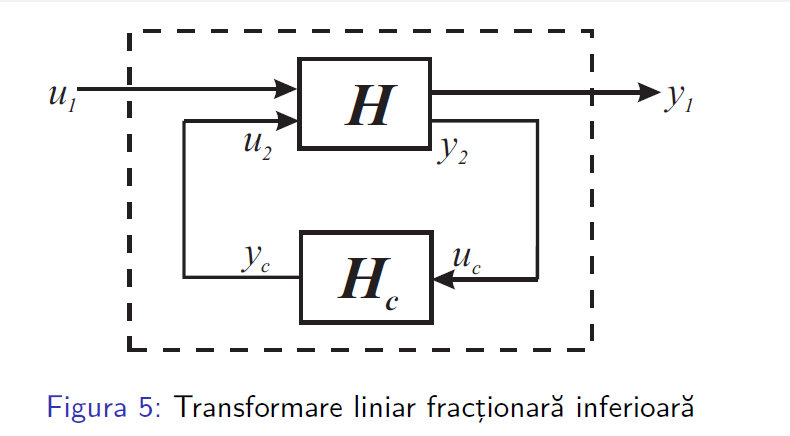

Hai sa vedem ca $T_{22}$ ia valorile instabile din T

disp('Valorile proprii din T_ss')

Valorile proprii din T_ss


eig(T_ss)

ans =     2.0000
    1.0000



disp('Valorile proprii din T22')

Valorile proprii din T22


eig(T22)

ans =     2.0000
    1.0000


Am luat K = -3 ca regulator pentru $T_{22}$

T(2,2)


ans =
 
     2 s + 4
  -------------
  s^2 - 3 s + 2
 
Continuous-time transfer function.



K = -3

K = -3


Kmatrix = [0 0;
           0 K];

Stab_22_cl = feedback(T(2,2), -K)


Stab_22_cl =
 
     2 s + 4
  --------------
  s^2 + 3 s + 14
 
Continuous-time transfer function.



disp(roots(Stab_22_cl.den{1}))

  -1.5000 + 3.4278i
  -1.5000 - 3.4278i




T_full_cl = feedback(T_ss, -Kmatrix);

disp('Polii sistemului complet in bucla inchisa:');

Polii sistemului complet in bucla inchisa:


disp(eig(T_full_cl.A));

  -1.5000 + 3.4278i
  -1.5000 - 3.4278i



Acum vad polii in bucla inchisa

polii_cl = pole(T_full_cl)

polii_cl =   -1.5000 + 3.4278i
  -1.5000 - 3.4278i



if all(real(polii_cl) < 0)
    disp('Sistemul a fost stabilizat cu succes folosind doar canalul 2,2.');
else
    disp('Sistemul NU este stabil.');
end

Sistemul a fost stabilizat cu succes folosind doar canalul 2,2.


## Problema 3

Am sistem minimal. In acest sens, fie $F\;\textrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\textrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\textrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{BF} & B & -L\\
F & I & 0\\
C+\mathrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{LC} & -\left(B+\mathrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

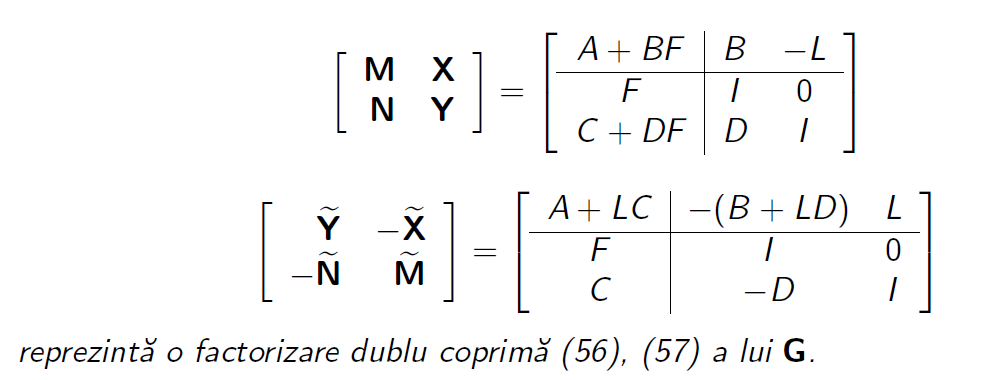

poli_dreapta = [-4 -5];
poli_stanga = [-5 -5];

F = -place(T_ss.A, T_ss.B, poli_stanga)

F =    -1.5923   -4.5923
   -1.7500    1.7500



L = -place(T_ss.A', T_ss.C', poli_dreapta)'

L =    -4.6977    2.2724
    1.6810   -4.5914


Sa verificam ca merge

disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(T_ss.A + T_ss.B * F))

   -5.0000
   -5.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(T_ss.A + L * T_ss.C));

   -4.0000
   -5.0000



Acum facem $M,N,\tilde{M} ,\tilde{N}$

NeTilda

M = ss(T_ss.A + T_ss.B * F, T_ss.B, F, eye(2,2))


M =
 
  A = 
               x1          x2
   x1          -5  -2.442e-15
   x2   -2.22e-16          -5
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1  -1.592  -4.592
   y2   -1.75    1.75
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


N = ss(T_ss.A + T_ss.B * F, T_ss.B, T_ss.C + T_ss.D * F, T_ss.D)


N =
 
  A = 
               x1          x2
   x1          -5  -2.442e-15
   x2   -2.22e-16          -5
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
            x1       x2
   y1  0.03078    2.031
   y2  -0.8116   -3.312
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


Tilda

Mtilde = ss(T_ss.A + L * T_ss.C, L, T_ss.C, eye(2,2))


Mtilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2    1.11e-15          -5
 
  B = 
           u1      u2
   x1  -4.698   2.272
   x2   1.681  -4.591
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


Ntilde = ss(T_ss.A + L * T_ss.C, -(T_ss.B + L * T_ss.D), ...
    T_ss.C, -T_ss.D)


Ntilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2    1.11e-15          -5
 
  B = 
           u1      u2
   x1  -3.243   1.243
   x2   3.621  -1.136
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0  -1
   y2  -1   0
 
Continuous-time state-space model.



Ntilde = -Ntilde


Ntilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2    1.11e-15          -5
 
  B = 
           u1      u2
   x1  -3.243   1.243
   x2   3.621  -1.136
 
  C = 
            x1       x2
   y1   -1.781  -0.2808
   y2  -0.7808   -1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


Ma pot uita la $G*M-N$ si $\tilde{M} *G-\tilde{N}$ pentru a vedea daca chiar este coprima factorizarea $G={\mathrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$ 

disp('Ne uitam mai intai in partea dreapta')

Ne uitam mai intai in partea dreapta


norm(T_ss * M - N, 'inf')

ans = 6.3480e-16


disp('Acum sa vedem partea stanga')

Acum sa vedem partea stanga


norm(Mtilde * T_ss - Ntilde, 'inf')

ans = 7.3428e-16

# **Un alt test**

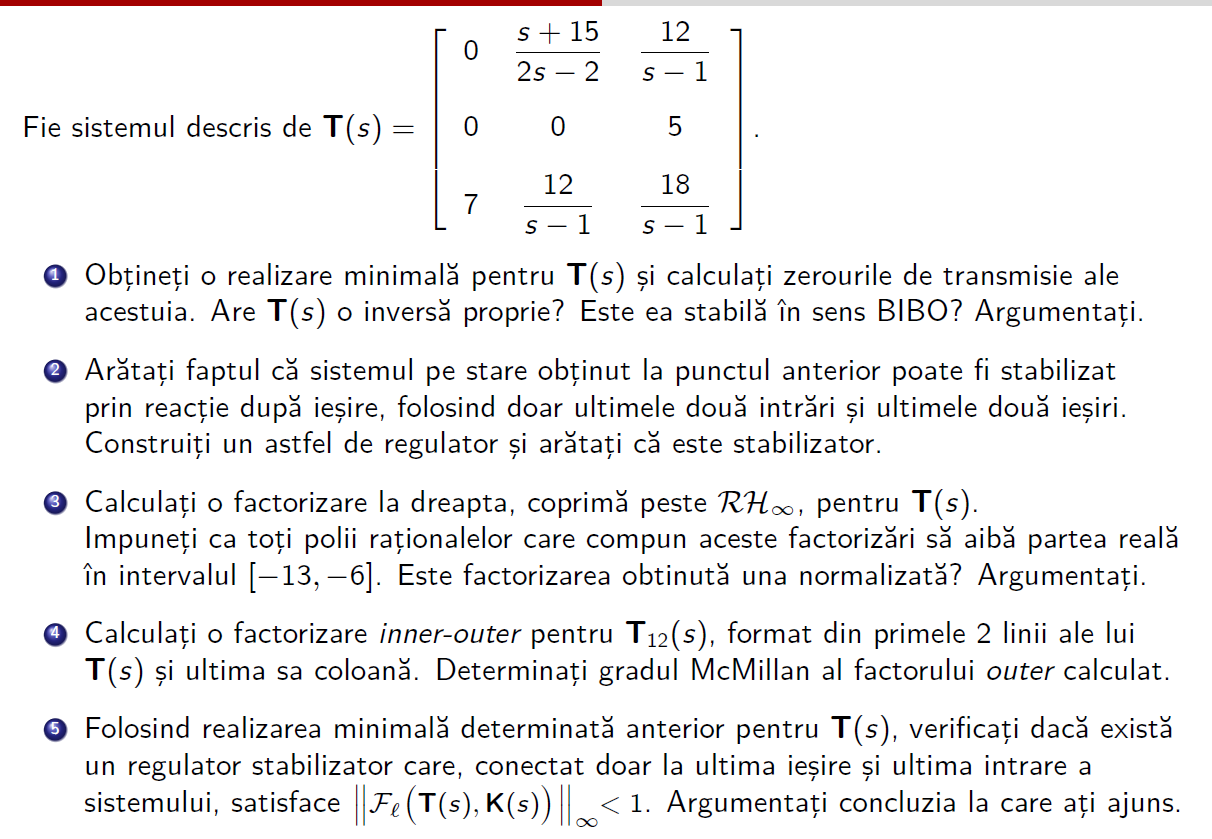

## Problema 1

clear
close all
clc

s = tf('s');

T = [0 (s + 15) / (2*s - 2) 12 / (s - 1);
     0 0 5;
     7 12 / (s - 1) 18 / (s - 1)]


T =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
   3:  7
 
  From input 2 to output...
       s + 15
   1:  -------
       2 s - 2
 
   2:  0
 
        12
   3:  -----
       s - 1
 
  From input 3 to output...
        12
   1:  -----
       s - 1
 
   2:  5
 
        18
   3:  -----
       s - 1
 
Continuous-time transfer function.



T_ss = ss(T,'min')


T_ss =
 
  A = 
       x1
   x1   1
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.



tzero(T)

ans =     1.0000
  -15.0000



Tinv = eye(size(T)) / T;

Tinv


Tinv =
 
  From input 1 to output...
       -3.429
   1:  ------
       s + 15
 
       2 s - 2
   2:  -------
       s + 15
 
   3:  0
 
  From input 2 to output...
       -0.5143 s + 0.5143
   1:  ------------------
        s^2 + 14 s - 15
 
        -4.8 s + 4.8
   2:  ---------------
       s^2 + 14 s - 15
 
   3:  0.2
 
  From input 3 to output...
   1:  0.1429
 
   2:  0
 
   3:  0
 
Continuous-time transfer function.



T * Tinv


ans =
 
  From input 1 to output...
       2 s^2 + 28 s - 30
   1:  -----------------
       2 s^2 + 28 s - 30
 
   2:  0
 
        5.684e-14 s + 5.684e-14
   3:  --------------------------
       s^3 + 29 s^2 + 195 s - 225
 
  From input 2 to output...
       8.882e-16 s^3 + 4.974e-14 s^2 - 1.421e-13 s + 7.105e-14
   1:  -------------------------------------------------------
                 2 s^4 + 24 s^3 - 84 s^2 + 88 s - 30
 
   2:  1
 
       -4.441e-16 s^5 + 3.411e-13 s^3 - 1.364e-12 s^2 + 1.819e-12 s - 5.684e-13
   3:  ------------------------------------------------------------------------
              s^6 + 26 s^5 + 111 s^4 - 724 s^3 + 1231 s^2 - 870 s + 225
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  1
 
Continuous-time transfer function.


% Vad ca face cat de cat forma de eye(3,3)

disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_ss.A))

     1



disp(isstable(T_ss))

   0



## Problema 2

T_ss


T_ss =
 
  A = 
       x1
   x1   1
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


T_mat_ss = [T_ss.A, T_ss.B;
            T_ss.C, T_ss.D]

T_mat_ss =     1.0000         0    2.2188    3.3282
    3.6056         0    0.5000         0
         0         0         0    5.0000
    5.4083    7.0000         0         0


Acum scriem $\left(A,B_2 ,C_2 ,D_2 \right)$

A2 = T_ss.A

A2 = 1


B2 = T_ss.B(:,2:3)

B2 =     2.2188    3.3282



C2 = T_ss.C(2:3,:)

C2 =          0
    5.4083



D2 = T_ss.D(2:3,2:3)

D2 =      0     5
     0     0



T22 = ss(A2, B2, C2, D2);
Pc2 = ctrb(A2, B2);
Po2 = obsv(A2, C2);

disp('Rangul sistemului de control:');

Rangul sistemului de control:


disp(rank(Pc2));

     1



disp('Rangul sistemului de observare:');

Rangul sistemului de observare:


disp(rank(Po2));

     1



Sistem minimal, doamne ajuta

Hai sa vedem ca $T_{22}$ ia valorile instabile din T

disp('Valorile proprii din T_ss')

Valorile proprii din T_ss


eig(T_ss)

ans = 1


disp('Valorile proprii din T22')

Valorile proprii din T22


eig(T22)

ans = 1

Minimal si asta

O sa iau K fix compensatorul Kalman

poli_dreapta = -10;
poli_stanga = -11;

F2 = -place(A2, B2, poli_stanga)

F2 =    -1.6641
   -2.4962



L2 = -place(A2', C2', poli_dreapta)'

L2 =          0   -2.0339



disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(A2 + B2 * F2))

  -11.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(A2 + L2 * C2));

   -10




K = ss(A2 + B2*F2 + L2*C2 + L2*D2*F2, -L2, ...
    F2,zeros(2,2))


K =
 
  A = 
        x1
   x1  -22
 
  B = 
          u1     u2
   x1      0  2.034
 
  C = 
           x1
   y1  -1.664
   y2  -2.496
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



T22_cl = feedback(T22, -K)


T22_cl =
 
  A = 
        x1   x2
   x1    1  -12
   x2   11  -22
 
  B = 
          u1     u2
   x1  2.219  3.328
   x2      0      0
 
  C = 
           x1      x2
   y1       0  -12.48
   y2   5.408       0
 
  D = 
       u1  u2
   y1   0   5
   y2   0   0
 
Continuous-time state-space model.



disp('Valorile proprii ale sistemului T22_cl in bucla inchisa:');

Valorile proprii ale sistemului T22_cl in bucla inchisa:


disp(pole(T22_cl));

  -10.0000
  -11.0000



Acum verific pentru tot sistemul ca sa vedem ca am facut bine

K_complet = blkdiag(ss(0),K)


K_complet =
 
  A = 
        x1
   x1  -22
 
  B = 
          u1     u2     u3
   x1      0      0  2.034
 
  C = 
           x1
   y1       0
   y2  -1.664
   y3  -2.496
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
Continuous-time state-space model.



T_cl = feedback(T_ss, -K_complet) % Reactie pozitiva


T_cl =
 
  A = 
        x1   x2
   x1    1  -12
   x2   11  -22
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
   x2  14.24      0      0
 
  C = 
            x1       x2
   y1    3.606  -0.8321
   y2        0   -12.48
   y3    5.408        0
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


% Aici mereu uitam sa pun - ala

disp('Valorile proprii ale sistemului in bucla inchisa:');

Valorile proprii ale sistemului in bucla inchisa:


disp(pole(T_cl));

  -10.0000
  -11.0000




if all(real(pole(T_cl)) < 0)
    disp('Sistemul a fost stabilizat cu succes!');
end

Sistemul a fost stabilizat cu succes!


## Problema 3

Am sistem minimal. In acest sens, fie $F\;\textrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\textrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\textrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{BF} & B & -L\\
F & I & 0\\
C+\mathrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{LC} & -\left(B+\mathrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

poli_F = -9;
poli_L = -11;

F = -place(T_ss.A, T_ss.B, poli_F)

F =          0
   -1.3868
   -2.0801



L = -place(T_ss.A', T_ss.C', poli_L)'

L =    -1.0241         0   -1.5361


Sa vedem daca merge

disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(T_ss.A + T_ss.B * F))

   -9.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(T_ss.A + L * T_ss.C));

  -11.0000



Acum facem $M,N,\tilde{M} ,\tilde{N}$

NeTilda

M = ss(T_ss.A + T_ss.B * F, T_ss.B, F, eye(3,3))


M =
 
  A = 
       x1
   x1  -9
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
           x1
   y1       0
   y2  -1.387
   y3   -2.08
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.


N = ss(T_ss.A + T_ss.B * F, T_ss.B, T_ss.C + T_ss.D * F, T_ss.D)


N =
 
  A = 
       x1
   x1  -9
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  2.912
   y2  -10.4
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


Tilda

Mtilde = ss(T_ss.A + L * T_ss.C, L, T_ss.C, eye(3,3))


Mtilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1  -1.024       0  -1.536
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.


Ntilde = ss(T_ss.A + L * T_ss.C, -(T_ss.B + L * T_ss.D), ...
    T_ss.C, -T_ss.D)


Ntilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1   10.75  -1.707  -3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
         u1    u2    u3
   y1     0  -0.5     0
   y2     0     0    -5
   y3    -7     0     0
 
Continuous-time state-space model.



Ntilde = -Ntilde


Ntilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1   10.75  -1.707  -3.328
 
  C = 
           x1
   y1  -3.606
   y2       0
   y3  -5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


Ma pot uita la $G*M-N$ si $\tilde{M} *G-\tilde{N}$ pentru a vedea daca chiar este coprima factorizarea $G={\textrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$ 

disp('Ne uitam mai intai in partea dreapta')

Ne uitam mai intai in partea dreapta


norm(T_ss * M - N, 'inf')

ans = 3.2776e-15


disp('Acum sa vedem partea stanga')

Acum sa vedem partea stanga


norm(Mtilde * T_ss - Ntilde, 'inf')

ans = 2.9221e-15